% MATLAB Script for Meningioma FT-IR Classification: Outlier Detection
% Phase 1: Setup & Initial Data Exploration
% Sub-Step: Outlier Detection via PCA, Hotelling T2 & Q-Statistic (SPE)

%clear; close all; clc; % Behalten Sie Ihre Präferenz bei
disp('Starting Outlier Detection Script (with T2 and Q-Statistic)...');

Starting Outlier Detection Script (with T2 and Q-Statistic)...



%% --- 1. Setup: Paths, Parameters, and Colors ---
disp('1. Setup: Paths, parameters, and colors...');

1. Setup: Paths, parameters, and colors...



% Project Root Directory (BITTE ANPASSEN FALLS NÖTIG)
projectBasePath = 'C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification'; 

% Directories
dataDir    = fullfile(projectBasePath, 'data');
resultsDir = fullfile(projectBasePath, 'results');
figuresDir = fullfile(projectBasePath, 'figures');

% Ensure results and figures directories exist
if ~isfolder(resultsDir); mkdir(resultsDir); end
if ~isfolder(figuresDir); mkdir(figuresDir); end

% Colors for visualization
colorWHO1 = [230, 153, 102] / 255; % Orange
colorWHO3 = [102, 179, 230] / 255; % Blue
colorOutlier = [255, 0, 0] / 255;  % Rot für allgemeine Ausreißer-Markierung
colorOutlierHighlight = [1 0.5 0]; % Orange-Rot für spezifische Ausreißer im T2-Q Plot

% Parameters for outlier detection
alpha = 0.01; % Signifikanzniveau für Hotelling T2 und Q-Statistic Schwellenwerte
varianceToExplainForT2 = 0.95; % PCA Varianz für T2 Berechnung (definiert k_model)

% Dateinamen-Präfix (aktuelles Datum Ihrer letzten Anfrage)
datePrefix = '20250514'; 
% Alternativ dynamisch: datePrefix = string(datetime('now','Format','yyyyMMdd'));

disp('Setup completed.');

Setup completed.



%% --- 2. Load and Prepare Training Data from dataTableTrain ---
disp('2. Loading and Preparing Training Data from dataTableTrain...');

2. Loading and Preparing Training Data from dataTableTrain...


% (Dieser Teil bleibt wie in Ihrem bestehenden Skript)
% Stellen Sie sicher, dass dataTableTrain, X_train, y_train_categorical, 
% Patient_ID_train, Original_Indices_train, 
% Original_Spectrum_Index_In_Sample_train, wavenumbers_roi, etc. hier geladen/erstellt werden.

% --- Anfang Ihres bestehenden Codes für Abschnitt 2 ---
try
    if ~exist('dataTableTrain', 'var')
        error(['dataTableTrain not found in workspace. Please load it before running this script. ' ...
               'Expected columns: CombinedSpectra, WHO_Grade, Diss_ID.']);
    end
    
    load(fullfile(dataDir, 'wavenumbers.mat'), 'wavenumbers_roi'); % Load wavenumbers
catch ME
    disp('Error during initial check for dataTableTrain or loading wavenumbers.mat.');
    disp('Ensure dataTableTrain is available in the workspace (with required columns),');
    disp('and wavenumbers.mat (with wavenumbers_roi) is in the dataDir.');
    rethrow(ME);
end

allSpectra_cell = {};
allLabels_cell = {};
allPatientIDs_cell = {};
allOriginalIndices_vec = []; 
allOriginalSpectrumIndices_Within_Sample_vec = []; 

disp('Extracting spectra, labels, and patient IDs from dataTableTrain...');

Extracting spectra, labels, and patient IDs from dataTableTrain...


for i = 1:height(dataTableTrain)
    spectraMatrix_Raw = dataTableTrain.CombinedSpectra{i};    
    if isempty(spectraMatrix_Raw) || ~isnumeric(spectraMatrix_Raw) || ndims(spectraMatrix_Raw) > 2
        warning('Row %d of dataTableTrain: CombinedSpectra does not contain a valid 2D numeric matrix or is empty. Skipping.', i);
        continue;
    end
    if size(spectraMatrix_Raw,1) == 0 % expliziter check nach Dimension 1
         warning('Row %d of dataTableTrain: CombinedSpectra cell yielded zero spectra after initial checks. Skipping this row.', i);
        continue;
    end

    spectraForCurrentSample = spectraMatrix_Raw; 
    numIndividualSpectra = size(spectraForCurrentSample, 1);
        
    allSpectra_cell{end+1,1} = spectraForCurrentSample;
    currentLabel = dataTableTrain.WHO_Grade(i);
    allLabels_cell{end+1,1} = repmat(currentLabel, numIndividualSpectra, 1);
    currentPatientID_val = dataTableTrain.Diss_ID{i};
    if iscell(currentPatientID_val) && length(currentPatientID_val)==1
        currentPatientID_str = currentPatientID_val{1};
    elseif ischar(currentPatientID_val)
        currentPatientID_str = currentPatientID_val;
    else
        error('Row %d of dataTableTrain: Diss_ID has an unexpected format.', i);
    end
    allPatientIDs_cell{end+1,1} = repmat({currentPatientID_str}, numIndividualSpectra, 1);
    allOriginalIndices_vec = [allOriginalIndices_vec; repmat(i, numIndividualSpectra, 1)];
    allOriginalSpectrumIndices_Within_Sample_vec = [allOriginalSpectrumIndices_Within_Sample_vec; (1:numIndividualSpectra)'];
end

if isempty(allSpectra_cell)
    error('No spectra could be extracted from dataTableTrain. Please check the CombinedSpectra column.');
end

X_train = cell2mat(allSpectra_cell);
y_train_categorical = cat(1, allLabels_cell{:});
Patient_ID_train = cat(1, allPatientIDs_cell{:});
Original_Indices_train = allOriginalIndices_vec; 
Original_Spectrum_Index_In_Sample_train = allOriginalSpectrumIndices_Within_Sample_vec;

y_train_numeric = zeros(length(y_train_categorical), 1);
categories_y = categories(y_train_categorical);
who1_cat_str = 'WHO-1'; who3_cat_str = 'WHO-3';
idx_who1_in_cat = find(strcmp(categories_y, who1_cat_str));
idx_who3_in_cat = find(strcmp(categories_y, who3_cat_str));
if ~isempty(idx_who1_in_cat); y_train_numeric(y_train_categorical == categories_y{idx_who1_in_cat}) = 1; end
if ~isempty(idx_who3_in_cat); y_train_numeric(y_train_categorical == categories_y{idx_who3_in_cat}) = 3; end
if any(y_train_numeric == 0) && ~all(y_train_numeric == 0)
    unmapped_mask = (y_train_numeric == 0);
    unmapped_cats = unique(y_train_categorical(unmapped_mask));
    warning('Some y_train labels were not mapped to numeric 1 or 3. Unmapped categories: %s.', strjoin(string(unmapped_cats),', '));
end
if all(y_train_numeric == 0) && ~isempty(y_train_categorical)
     error('No y_train labels were mapped to numeric 1 or 3. Check WHO_Grade values.');
end
y_train = y_train_categorical; 

disp(['Training data extracted: ' num2str(size(X_train, 1)) ' spectra, ' num2str(size(X_train, 2)) ' wavenumbers.']);

Training data extracted: 33792 spectra, 441 wavenumbers.


if size(X_train, 2) ~= length(wavenumbers_roi)
    warning('MISMATCH: Features in X_train (%d) vs. length of wavenumbers_roi (%d).', size(X_train,2), length(wavenumbers_roi));
end
disp('Data extraction and preparation completed.');

Data extraction and preparation completed.


% --- Ende Ihres bestehenden Codes für Abschnitt 2 ---


%% --- 3. Perform PCA on Training Data ---
disp('3. Performing PCA on training data...');

3. Performing PCA on training data...


if isempty(X_train)
    error('X_train is empty. Cannot perform PCA.');
end
[coeff_train, score_train, latent_train, tsquared_builtin, explained_train, mu_train] = pca(X_train, 'Algorithm','svd'); % 'tsquared_builtin' ist T² von pca()

disp('PCA completed.');

PCA completed.


disp(['Variance explained by first PC: ' num2str(explained_train(1), '%.2f') '%']);

Variance explained by first PC: 50.17%



% Anzahl der PCs für das Modell (k_model), basierend auf erklärter Varianz
cumulativeVariance = cumsum(explained_train);
k_model = find(cumulativeVariance >= varianceToExplainForT2*100, 1, 'first');
if isempty(k_model)
    k_model = length(explained_train); 
end
if k_model == 0 && ~isempty(explained_train)
    k_model = 1;
end
if isempty(explained_train) || k_model == 0 
    error('Could not determine a valid number of components (k_model). Check PCA results.');
end
disp(['Number of PCs for PCA model (k_model, explaining >= ' num2str(varianceToExplainForT2*100) '% variance): ' num2str(k_model)]);

Number of PCs for PCA model (k_model, explaining >= 95% variance): 6



%% --- 4. Calculate Hotelling's T-Squared Statistic (T²) ---
disp('4. Calculating Hotelling T-Squared statistic (T²)...');

4. Calculating Hotelling T-Squared statistic (T²)...


% Die 'pca' Funktion liefert T²-Werte direkt, wenn genügend Samples vorhanden sind.
% Diese basieren auf allen PCs bis zum Rang der Daten. 
% Für Konsistenz mit der Q-Statistik (die auf k_model PCs basiert), berechnen wir T²
% oft auch explizit für die k_model PCs.
% Wenn Sie tsquared_builtin verwenden möchten, beachten Sie, dass es anders berechnet sein könnte.

% Explizite Berechnung von T² für k_model Komponenten:
score_k_model = score_train(:, 1:k_model);
lambda_k_model = latent_train(1:k_model); 
% Sicherstellen, dass keine Eigenwerte für die Division null sind
lambda_k_model(lambda_k_model <= eps) = eps; % eps ist eine kleine positive Zahl

T2_values = sum(bsxfun(@rdivide, score_k_model.^2, lambda_k_model'), 2);
disp('Hotelling T-Squared values (for k_model PCs) calculated.');

Hotelling T-Squared values (for k_model PCs) calculated.



%% --- 5. Determine Outlier Threshold for T² ---
disp('5. Determining outlier threshold for T²...');

5. Determining outlier threshold for T²...


n_samples = size(X_train, 1);
if n_samples > k_model && k_model > 0
    % F-Verteilung basierter Schwellenwert
    T2_threshold = ((k_model * (n_samples - 1)) / (n_samples - k_model)) * finv(1 - alpha, k_model, n_samples - k_model);
    disp(['Hotelling T2 threshold (F-dist, alpha=' num2str(alpha) ', df1=' num2str(k_model) ', df2=' num2str(n_samples - k_model) '): ' num2str(T2_threshold)]);
else
    disp('Warning: Cannot use F-distribution for T2 threshold. Falling back to Chi-squared or problem with k_model/n_samples.');
    if k_model > 0
        T2_threshold = chi2inv(1 - alpha, k_model); % Chi-Quadrat basierter Schwellenwert
        disp(['Hotelling T2 threshold (Chi2-dist, alpha=' num2str(alpha) ', df=' num2str(k_model) '): ' num2str(T2_threshold)]);
    else
        error('k_model is 0, cannot calculate T2_threshold.');
    end
end

Hotelling T2 threshold (F-dist, alpha=0.01, df1=6, df2=33786): 16.8176


if isnan(T2_threshold) || isinf(T2_threshold)
    error('Calculated T2_threshold is NaN or Inf. Check parameters and input data.');
end

%% --- 6. NEU: Calculate Q-Statistic (SPE - Squared Prediction Error) ---
disp('6. Calculating Q-Statistic (SPE)...');

6. Calculating Q-Statistic (SPE)...



% Rekonstruktion der Daten basierend auf k_model PCs
X_reconstructed = score_train(:, 1:k_model) * coeff_train(:, 1:k_model)' + mu_train;

% Residuen
E_residuals = X_train - X_reconstructed;

% Q-Werte (Summe der quadrierten Residuen pro Beobachtung)
Q_values = sum(E_residuals.^2, 2);
disp('Q-Statistic values calculated.');

Q-Statistic values calculated.



%% --- 7. NEU: Determine Outlier Threshold for Q-Statistic ---
disp('7. Determining outlier threshold for Q-Statistic...');

7. Determining outlier threshold for Q-Statistic...


% Theoretischer Schwellenwert nach Jackson und Mudholkar
% Benötigt Eigenwerte der *nicht* im Modell verwendeten PCs

num_total_pcs_latent = length(latent_train); % Gesamtzahl der von PCA gefundenen Eigenwerte

if k_model < num_total_pcs_latent
    discarded_eigenvalues = latent_train(k_model+1:end);
    % Setze sehr kleine oder negative Eigenwerte auf einen kleinen positiven Wert, um numerische Probleme zu vermeiden
    discarded_eigenvalues(discarded_eigenvalues <= eps) = eps;

    theta1 = sum(discarded_eigenvalues);
    theta2 = sum(discarded_eigenvalues.^2);
    theta3 = sum(discarded_eigenvalues.^3);

    if theta1 <= eps % Keine signifikante restliche Varianz
        Q_threshold = 0;
        disp('Q_threshold: No significant residual variance (theta1 approx 0), Q_threshold set to 0.');
    elseif theta2 <= eps % Notwendig für h0 Berechnung
        Q_threshold = theta1 * (1 + norminv(1-alpha)*0/theta1)^(1/1); % Vereinfachung falls theta2=0
         disp('Q_threshold: theta2 is approx 0. Simplified Q threshold used.');
    else
        h0 = 1 - (2 * theta1 * theta3) / (3 * theta2^2);
        if h0 <= eps % h0 muss positiv sein für die Formel
             h0_original = h0;
             h0 = 1; % Fallback, wenn h0 nicht sinnvoll ist (oft bei wenigen verworfenen PCs)
             disp(['Warning: h0 calculation resulted in ' num2str(h0_original) '. Using h0=1 as fallback.']);
        end
        
        ca = norminv(1 - alpha); % z.B. 1.96 für alpha = 0.025 (wenn man 0.05 zweiseitig meint) oder 1.645 für alpha=0.05 (einseitig)
                                  % Da Q immer positiv ist, ist ein einseitiger Test üblich.
        
        % Term in der Klammer: val = c_alpha * sqrt(2*theta2*h0^2)/theta1 + 1 + theta2*h0*(h0-1)/(theta1^2)
        term_sqrt = ca * sqrt(2 * theta2 * h0^2) / theta1;
        term_h0_manage = (theta2 * h0 * (h0 - 1)) / (theta1^2);
        
        val_in_bracket = term_sqrt + 1 + term_h0_manage;
        
        if val_in_bracket < 0 % Kann passieren, wenn h0 sehr klein und der letzte Term negativ dominant wird
            disp(['Warning: Value inside bracket for Q_threshold is negative (' num2str(val_in_bracket) '). This can indicate issues with h0 or few discarded PCs. Using a simplified threshold.']);
            % Vereinfachter Ansatz oder Perzentil-basierter Ansatz als Fallback
            % Z.B. einfacher Chi2-Approximation für Q: Q_alpha = g * chi2inv(1-alpha, v)
            % g = theta2 / theta1; v = theta1^2 / theta2;
            % Q_threshold = (theta2/theta1) * chi2inv(1-alpha, theta1^2/theta2);
            % Oder noch einfacher:
            Q_threshold = prctile(Q_values, (1-alpha)*100); % Empirischer Schwellenwert als Fallback
            disp(['Using empirical Q_threshold (percentile): ' num2str(Q_threshold)]);
        else
            Q_threshold = theta1 * (val_in_bracket)^(1/h0);
            disp(['Q-Statistic threshold (alpha=' num2str(alpha) '): ' num2str(Q_threshold)]);
        end
    end
else
    % Alle PCs wurden im Modell verwendet, theoretisch keine Residuen für Q
    Q_threshold = 0; 
    disp('Q_threshold: All PCs used in model (k_model >= num_total_pcs_latent), Q_threshold set to 0.');
    if any(Q_values > eps)
        warning('Q_values are non-zero even though all PCs supposedly used. Check k_model and PCA rank.');
    end
end

Q-Statistic threshold (alpha=0.01): 0.0060795


if isnan(Q_threshold) || isinf(Q_threshold)
    warning('Calculated Q_threshold is NaN or Inf. Using empirical percentile as fallback.');
    Q_threshold = prctile(Q_values, (1-alpha)*100);
    disp(['Using empirical Q_threshold (percentile): ' num2str(Q_threshold)]);
end


%% --- 8. Identify Outliers (based on T² and Q) ---
disp('8. Identifying outliers based on T2 and Q...');

8. Identifying outliers based on T2 and Q...


outlier_T2_logical = T2_values > T2_threshold;
outlier_Q_logical = Q_values > Q_threshold;

% Kombinierte Ausreißer: Jeder, der mindestens einen Schwellenwert überschreitet
outlier_indices_logical = outlier_T2_logical | outlier_Q_logical;

num_outliers = sum(outlier_indices_logical);
num_outliers_T2_only = sum(outlier_T2_logical & ~outlier_Q_logical);
num_outliers_Q_only = sum(~outlier_T2_logical & outlier_Q_logical);
num_outliers_Both_T2_Q = sum(outlier_T2_logical & outlier_Q_logical);

disp([num2str(num_outliers) ' total outliers identified.']);

3179 total outliers identified.


disp(['   - T2 only: ' num2str(num_outliers_T2_only)]);

   - T2 only: 1304


disp(['   - Q only: ' num2str(num_outliers_Q_only)]);

   - Q only: 761


disp(['   - Both T2 & Q: ' num2str(num_outliers_Both_T2_Q)]);

   - Both T2 & Q: 1114



outlier_indices_numeric = find(outlier_indices_logical);

if num_outliers > 0
    disp('Global indices of identified outliers (relative to X_train):'); disp(outlier_indices_numeric');
    Patient_ID_outliers = Patient_ID_train(outlier_indices_logical);
    disp('Patient IDs of identified outliers:'); disp(unique(Patient_ID_outliers)'); 
else
    disp('No outliers identified in X_train according to T2 and Q thresholds.');
end

Global indices of identified outliers (relative to X_train):
  Columns 1 through 2730

          10          15          16          26          32          48         120         130         147         164         215         258         274         275         290         340         359         368         375         390         394         395         396         397         398         399         400         406         422         438         453         487         488         542         677         715         716         734         735         800        1092        1288        1442        2063        2064        2336        3075        3080        3107        3108        3122        3124        3128        3150        3160        3168        3176        3178        3186        3190        3206        3207        3218        3222        3234        3235        3250        3251        3252        3253        3267        3270        3271        3272        3279        3282 

Patient IDs of identified outliers:
    {'MEN-002-01'}    {'MEN-003-01'}    {'MEN-004-01'}    {'MEN-005-01'}    {'MEN-010-01'}    {'MEN-011-01'}    {'MEN-014-01'}    {'MEN-016-01'}    {'MEN-019-01'}    {'MEN-020-01'}    {'MEN-022-01'}    {'MEN-023-01'}    {'MEN-033-01'}    {'MEN-037-01'}    {'MEN-040-01'}    {'MEN-044-02'}    {'MEN-050-01'}    {'MEN-080-01'}    {'MEN-081-01'}    {'MEN-081-02'}    {'MEN-083-01'}    {'MEN-083-04'}    {'MEN-087-01'}    {'MEN-093-01'}    {'MEN-097-01'}    {'MEN-098-01'}    {'MEN-099-01'}    {'MEN-101-01'}




%% --- 9. Visualize Results ---
disp('9. Visualizing results...');

9. Visualizing results...


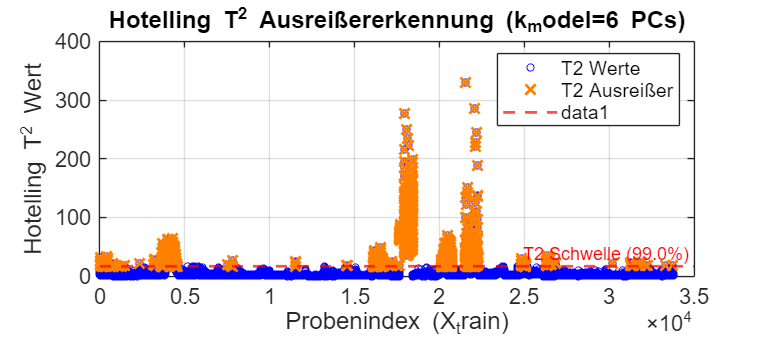


% Plot 1: Hotelling's T-Squared Values
figT2Individual = figure('Name', 'Hotelling T2 Outlier Detection', 'Position', [100, 100, 900, 400]); % Korrigierter Variablenname
plot(1:length(T2_values), T2_values, 'ob', 'MarkerSize', 4, 'DisplayName', 'T2 Werte'); hold on;
plot(find(outlier_T2_logical), T2_values(outlier_T2_logical), 'x', 'Color', colorOutlierHighlight, 'MarkerSize', 8, 'LineWidth', 1.5, 'DisplayName', 'T2 Ausreißer');
yline(T2_threshold, '--r', ['T2 Schwelle (' num2str((1-alpha)*100, '%.1f') '%)'], 'LineWidth', 1.5);
hold off; xlabel('Probenindex (X_train)'); ylabel('Hotelling T^2 Wert');
title(['Hotelling T^2 Ausreißererkennung (k_model=' num2str(k_model) ' PCs)'], 'FontSize', 14);
legend('show', 'Location', 'northeast'); grid on; set(gca, 'FontSize', 12);

figName_T2_tiff = strcat(datePrefix, '_PCA_HotellingT2_Plot_ext.tiff');
exportgraphics(figT2Individual, fullfile(figuresDir, figName_T2_tiff), 'Resolution', 300); % Korrigierten Variablennamen verwenden

savefig(figT2Individual, fullfile(figuresDir, strrep(figName_T2_tiff,'.tiff','.fig'))); % Korrigierten Variablennamen verwenden
disp(['T2 plot saved as: ' fullfile(figuresDir, figName_T2_tiff)]);

T2 plot saved as: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\figures\20250514_PCA_HotellingT2_Plot_ext.tiff


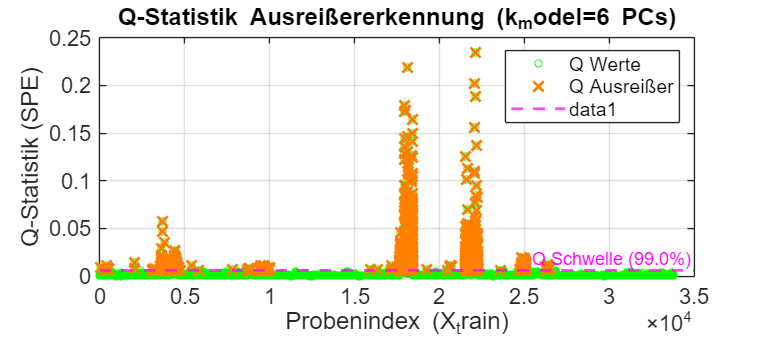


% Plot 2: Q-Statistic Values (NEU)
figQ = figure('Name', 'Q-Statistic (SPE) Outlier Detection', 'Position', [150, 150, 900, 400]);
plot(1:length(Q_values), Q_values, 'og', 'MarkerSize', 4, 'DisplayName', 'Q Werte'); hold on;
plot(find(outlier_Q_logical), Q_values(outlier_Q_logical), 'x', 'Color', colorOutlierHighlight, 'MarkerSize', 8, 'LineWidth', 1.5, 'DisplayName', 'Q Ausreißer');
yline(Q_threshold, '--m', ['Q Schwelle (' num2str((1-alpha)*100, '%.1f') '%)'], 'LineWidth', 1.5);
hold off; xlabel('Probenindex (X_train)'); ylabel('Q-Statistik (SPE)');
title(['Q-Statistik Ausreißererkennung (k_model=' num2str(k_model) ' PCs)'], 'FontSize', 14);
legend('show', 'Location', 'northeast'); grid on; set(gca, 'FontSize', 12);
figName_Q_tiff = strcat(datePrefix, '_PCA_Q_Statistic_Plot.tiff');
exportgraphics(figQ, fullfile(figuresDir, figName_Q_tiff), 'Resolution', 300);

savefig(figQ, fullfile(figuresDir, strrep(figName_Q_tiff,'.tiff','.fig')));
disp(['Q-Statistic plot saved as: ' fullfile(figuresDir, figName_Q_tiff)]);

Q-Statistic plot saved as: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\figures\20250514_PCA_Q_Statistic_Plot.tiff


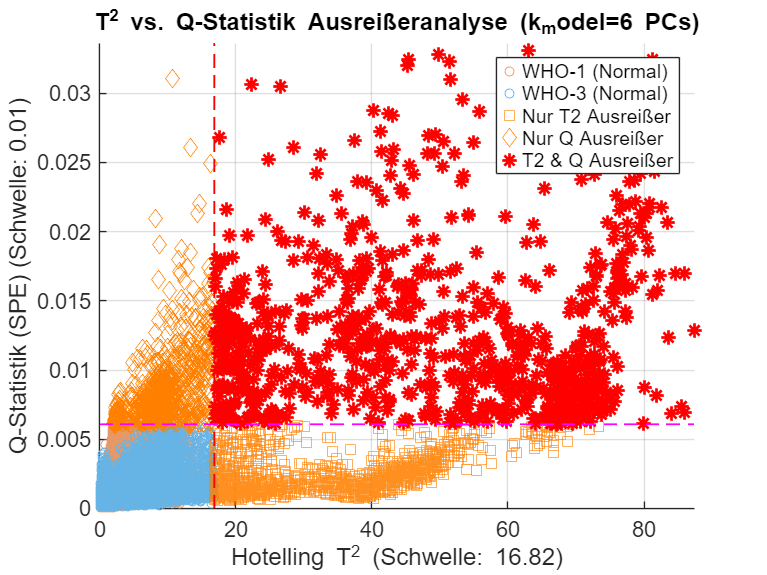



% Plot 3: T² vs. Q Plot (NEU)
figT2Q = figure('Name', 'T2 vs Q Outlier Plot', 'Position', [200, 200, 1000, 750]);
hold on;
% Nicht-Ausreißer (nach neuer Definition)
non_outliers_final = ~outlier_indices_logical;
isWHO1_non_outlier_final = (y_train_numeric == 1) & non_outliers_final;
isWHO3_non_outlier_final = (y_train_numeric == 3) & non_outliers_final;

if any(isWHO1_non_outlier_final)
    plot(T2_values(isWHO1_non_outlier_final), Q_values(isWHO1_non_outlier_final), 'o', 'Color', colorWHO1, 'MarkerSize', 5, 'DisplayName', 'WHO-1 (Normal)');
end
if any(isWHO3_non_outlier_final)
    plot(T2_values(isWHO3_non_outlier_final), Q_values(isWHO3_non_outlier_final), 'o', 'Color', colorWHO3, 'MarkerSize', 5, 'DisplayName', 'WHO-3 (Normal)');
end

% Ausreißer (alle kombinierten)
if num_outliers > 0
    % plot(T2_values(outlier_indices_logical), Q_values(outlier_indices_logical), 'x', 'Color', colorOutlier, 'MarkerSize', 8, 'LineWidth', 1, 'DisplayName', 'Ausreißer (T2 oder Q)');
    % Detailliertere Markierung der Ausreißertypen
    plot(T2_values(outlier_T2_logical & ~outlier_Q_logical), Q_values(outlier_T2_logical & ~outlier_Q_logical), 's', 'Color', colorOutlierHighlight, 'MarkerSize', 7, 'DisplayName', 'Nur T2 Ausreißer');
    plot(T2_values(~outlier_T2_logical & outlier_Q_logical), Q_values(~outlier_T2_logical & outlier_Q_logical), 'd', 'Color', colorOutlierHighlight, 'MarkerSize', 7, 'DisplayName', 'Nur Q Ausreißer');
    plot(T2_values(outlier_T2_logical & outlier_Q_logical), Q_values(outlier_T2_logical & outlier_Q_logical), '*', 'Color', colorOutlier, 'MarkerSize', 8, 'LineWidth',1.5, 'DisplayName', 'T2 & Q Ausreißer');
end

% Schwellenwerte einzeichnen
line([T2_threshold, T2_threshold], [0, max(Q_values)], 'Color', 'r', 'LineStyle', '--', 'LineWidth', 1, 'HandleVisibility','off');
line([0, max(T2_values)], [Q_threshold, Q_threshold], 'Color', 'm', 'LineStyle', '--', 'LineWidth', 1, 'HandleVisibility','off');

% Achsen ggf. logarithmisch für bessere Visualisierung, falls Werte stark variieren
% set(gca, 'XScale', 'log', 'YScale', 'log'); % Bei Bedarf
xlabel(['Hotelling T^2 (Schwelle: ' num2str(T2_threshold,'%.2f') ')']); 
ylabel(['Q-Statistik (SPE) (Schwelle: ' num2str(Q_threshold,'%.2f') ')']);
title(['T^2 vs. Q-Statistik Ausreißeranalyse (k_model=' num2str(k_model) ' PCs)'], 'FontSize', 14);
legend('show', 'Location', 'northeast'); grid on; set(gca, 'FontSize', 12);
% Ggf. Achsenlimits anpassen, um nicht von einzelnen Extremwerten dominiert zu werden
xlim_max_T2 = prctile([T2_values; T2_threshold*1.1], 99.5); % Oberes Limit für T2-Achse
ylim_max_Q = prctile([Q_values; Q_threshold*1.1], 99.5);   % Oberes Limit für Q-Achse
if xlim_max_T2 > T2_threshold; xlim([0 xlim_max_T2]); end
if ylim_max_Q > Q_threshold; ylim([0 ylim_max_Q]); end

hold off;
figName_T2Q_tiff = strcat(datePrefix, '_PCA_T2_vs_Q_Plot.tiff');
exportgraphics(figT2Q, fullfile(figuresDir, figName_T2Q_tiff), 'Resolution', 300);

savefig(figT2Q, fullfile(figuresDir, strrep(figName_T2Q_tiff,'.tiff','.fig')));
disp(['T2 vs Q plot saved as: ' fullfile(figuresDir, figName_T2Q_tiff)]);

T2 vs Q plot saved as: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\figures\20250514_PCA_T2_vs_Q_Plot.tiff


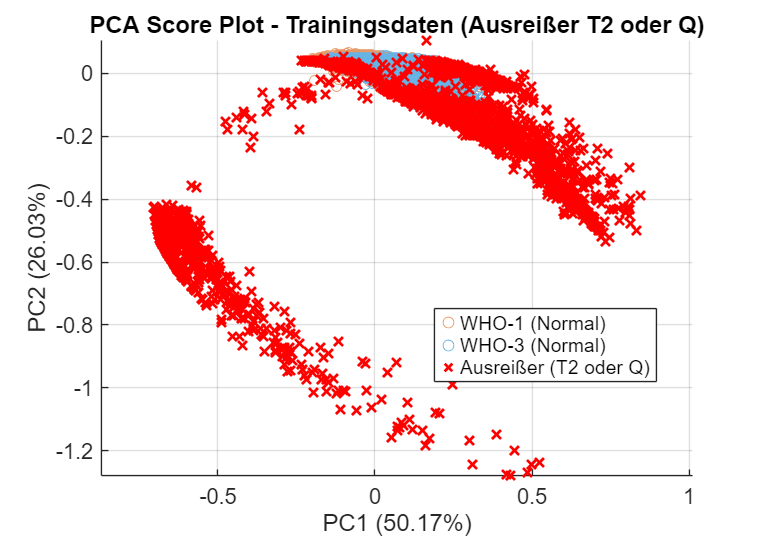



% Plot 4: PCA Score Plot (bestehender Plot, Outlier-Markierung basiert nun auf T2 ODER Q)
figPCA = figure('Name', 'PCA Score Plot mit Ausreißern (T2 oder Q)', 'Position', [250, 250, 1000, 700]);
hold on;
pc_for_x_axis = 1;
pc_for_y_axis = 2;
if size(score_train,2) < 2; pc_for_y_axis = 1; end

if any(isWHO1_non_outlier_final)
    scatter(score_train(isWHO1_non_outlier_final, pc_for_x_axis), score_train(isWHO1_non_outlier_final, pc_for_y_axis), 30, colorWHO1, 'o', 'DisplayName', 'WHO-1 (Normal)');
end
if any(isWHO3_non_outlier_final)
    scatter(score_train(isWHO3_non_outlier_final, pc_for_x_axis), score_train(isWHO3_non_outlier_final, pc_for_y_axis), 30, colorWHO3, 'o', 'DisplayName', 'WHO-3 (Normal)');
end
if num_outliers > 0 && pc_for_x_axis <= size(score_train,2) && pc_for_y_axis <= size(score_train,2)
    scatter(score_train(outlier_indices_logical, pc_for_x_axis), score_train(outlier_indices_logical, pc_for_y_axis), ...
            50, colorOutlier, 'x', 'LineWidth', 1.5, 'DisplayName', 'Ausreißer (T2 oder Q)');
end
hold off; 
xlabel_str = ['PC' num2str(pc_for_x_axis) ' (' num2str(explained_train(pc_for_x_axis), '%.2f') '%)'];
ylabel_str = ['PC' num2str(pc_for_y_axis) ' (' num2str(explained_train(min(pc_for_y_axis,length(explained_train))), '%.2f') '%)']; % Min für Y-Achse falls nur 1 PC
if pc_for_y_axis == 1; ylabel_str = ['(Nur PC' num2str(pc_for_x_axis) ' verfügbar)']; end
xlabel(xlabel_str); ylabel(ylabel_str);
title_str = ['PCA Score Plot - Trainingsdaten (Ausreißer T2 oder Q)'];
title(title_str, 'FontSize', 14);
legend('show', 'Location', 'best'); grid on; axis equal; set(gca, 'FontSize', 12);
figName_PCA_tiff = strcat(datePrefix, '_PCA_ScorePlot_Outliers_T2Q.tiff');
exportgraphics(figPCA, fullfile(figuresDir, figName_PCA_tiff), 'Resolution', 300);

savefig(figPCA, fullfile(figuresDir, strrep(figName_PCA_tiff,'.tiff','.fig')));
disp(['PCA score plot (T2/Q outliers) saved as: ' fullfile(figuresDir, figName_PCA_tiff)]);

PCA score plot (T2/Q outliers) saved as: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\figures\20250514_PCA_ScorePlot_Outliers_T2Q.tiff



disp('Visualization completed.');

Visualization completed.


Creating 3D PCA Score Plot (PC1-PC3)...


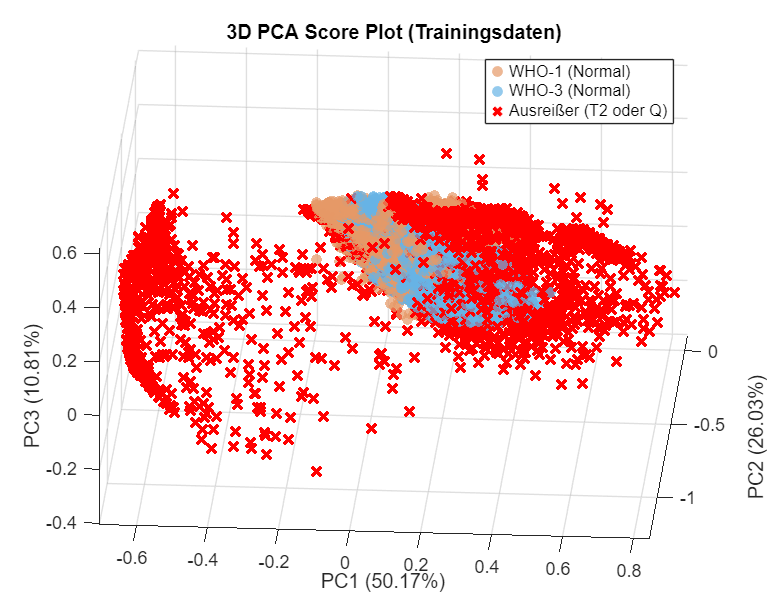

3D PCA Score Plot (PC1-3) gespeichert als: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\figures\20250514_PCA_ScorePlot3D_PC123.tiff



% Plot 5: 3D PCA Score Plot (PC1 vs PC2 vs PC3) (NEU)
if size(score_train, 2) >= 3 % Prüfen, ob mindestens 3 PCs vorhanden sind
    disp('Creating 3D PCA Score Plot (PC1-PC3)...');
    figPCA3D = figure('Name', '3D PCA Score Plot (PC1-3)', 'Position', [300, 100, 950, 750]); % Angepasste Position und Größe
    ax3D = axes(figPCA3D); % Explizites Achsen-Handle für 3D-Operationen
    hold(ax3D, 'on');

    % Marker-Größen
    markerSizeNormal_3D = 35; % Etwas größer für 3D
    markerSizeOutlier_3D = 60;

    % Verwendung der finalen Ausreißerdefinition (T2 oder Q)
    % non_outliers_final und y_train_numeric sollten aus dem vorherigen Kontext verfügbar sein
    % outlier_indices_logical ist die kombinierte Ausreißermaske
    
    isWHO1_non_outlier_final_plot = (y_train_numeric == 1) & ~outlier_indices_logical;
    isWHO3_non_outlier_final_plot = (y_train_numeric == 3) & ~outlier_indices_logical;

    % Plotten der Nicht-Ausreißer
    if any(isWHO1_non_outlier_final_plot)
        scatter3(ax3D, score_train(isWHO1_non_outlier_final_plot, 1), ...
                 score_train(isWHO1_non_outlier_final_plot, 2), ...
                 score_train(isWHO1_non_outlier_final_plot, 3), ...
                 markerSizeNormal_3D, colorWHO1, 'o', 'filled', ...
                 'DisplayName', 'WHO-1 (Normal)', 'MarkerFaceAlpha', 0.7, 'MarkerEdgeAlpha', 0.9);
    end
    if any(isWHO3_non_outlier_final_plot)
        scatter3(ax3D, score_train(isWHO3_non_outlier_final_plot, 1), ...
                 score_train(isWHO3_non_outlier_final_plot, 2), ...
                 score_train(isWHO3_non_outlier_final_plot, 3), ...
                 markerSizeNormal_3D, colorWHO3, 'o', 'filled', ...
                 'DisplayName', 'WHO-3 (Normal)', 'MarkerFaceAlpha', 0.7, 'MarkerEdgeAlpha', 0.9);
    end

    % Plotten der Ausreißer (kombinierte T2/Q Logik)
    if any(outlier_indices_logical)
        scatter3(ax3D, score_train(outlier_indices_logical, 1), ...
                 score_train(outlier_indices_logical, 2), ...
                 score_train(outlier_indices_logical, 3), ...
                 markerSizeOutlier_3D, colorOutlier, 'x', 'LineWidth', 2, ... % Dickeres 'x'
                 'DisplayName', 'Ausreißer (T2 oder Q)');
    end
    
    hold(ax3D, 'off');
    
    % Achsenbeschriftungen mit Prozent der erklärten Varianz
    xlabel(ax3D, ['PC1 (' num2str(explained_train(1), '%.2f') '%)'], 'FontSize', 11);
    ylabel(ax3D, ['PC2 (' num2str(explained_train(2), '%.2f') '%)'], 'FontSize', 11);
    zlabel(ax3D, ['PC3 (' num2str(explained_train(3), '%.2f') '%)'], 'FontSize', 11);
    
    title(ax3D, '3D PCA Score Plot (Trainingsdaten)', 'FontSize', 14);
    legend(ax3D, 'show', 'Location', 'northeast', 'FontSize', 9);
    grid(ax3D, 'on');
    axis(ax3D, 'tight'); % Passt Achsen eng an die Daten an
    view(ax3D, -30, 20);  % Guter Start-Blickwinkel (Azimut, Elevation), anpassbar
    rotate3d(ax3D, 'on'); % Interaktives Drehen mit der Maus erlauben
    set(ax3D, 'FontSize', 10);

    % Speichern der Abbildung
    % datePrefix sollte bereits definiert sein, z.B. '20250514'
    figName_PCA3D_tiff = strcat(datePrefix, '_PCA_ScorePlot3D_PC123.tiff');
    exportgraphics(figPCA3D, fullfile(figuresDir, figName_PCA3D_tiff), 'Resolution', 300);
    figName_PCA3D_fig = strcat(datePrefix, '_PCA_ScorePlot3D_PC123.fig');
    savefig(figPCA3D, fullfile(figuresDir, figName_PCA3D_fig));
    disp(['3D PCA Score Plot (PC1-3) gespeichert als: ' fullfile(figuresDir, figName_PCA3D_tiff)]);
else
    disp('Info: 3D PCA Score Plot wird übersprungen, da weniger als 3 Hauptkomponenten verfügbar sind.');
end



%% --- 10. Save Outlier Information (erweitert um Q-Statistik) ---
disp('10. Saving outlier information (T2 and Q)...');

10. Saving outlier information (T2 and Q)...


outlierInfo = struct();
outlierInfo.scriptRunDate = string(datetime(datePrefix,'InputFormat','yyyyMMdd','Format','yyyy-MM-dd'));
outlierInfo.alpha_T2_Q = alpha;
outlierInfo.varianceToExplainForPCAmodel = varianceToExplainForT2;
outlierInfo.numComponentsInPCAmodel_k_model = k_model;

outlierInfo.T2_values = T2_values;
outlierInfo.T2_threshold = T2_threshold;
outlierInfo.Q_values = Q_values;
outlierInfo.Q_threshold = Q_threshold;

outlierInfo.outlier_global_indices_in_X_train = outlier_indices_numeric;
outlierInfo.is_T2_outlier_flag = outlier_T2_logical(outlier_indices_logical); % Für die als Gesamt-Ausreißer markierten
outlierInfo.is_Q_outlier_flag = outlier_Q_logical(outlier_indices_logical);   % Für die als Gesamt-Ausreißer markierten

if num_outliers > 0
    outlierInfo.outlier_Original_Indices_dataTableTrain_Row = Original_Indices_train(outlier_indices_logical);
    outlierInfo.outlier_Original_Spectrum_Index_In_Sample = Original_Spectrum_Index_In_Sample_train(outlier_indices_logical);
    outlierInfo.Patient_ID_outliers = Patient_ID_train(outlier_indices_logical);
    outlierInfo.T2_values_of_outliers = T2_values(outlier_indices_logical);
    outlierInfo.Q_values_of_outliers = Q_values(outlier_indices_logical);
else
    % Leere Felder initialisieren
    outlierInfo.outlier_Original_Indices_dataTableTrain_Row = [];
    outlierInfo.outlier_Original_Spectrum_Index_In_Sample = [];
    outlierInfo.Patient_ID_outliers = {};
    outlierInfo.T2_values_of_outliers = [];
    outlierInfo.Q_values_of_outliers = [];
end
outlierInfo.analysisDate = string(datetime('now','Format','yyyy-MM-dd HH:mm:ss'));

resultsFilename_mat = strcat(datePrefix, '_PCA_HotellingT2_Q_OutlierInfo.mat');
save(fullfile(resultsDir, resultsFilename_mat), 'outlierInfo');
disp(['Outlier information (T2 & Q) saved in: ' fullfile(resultsDir, resultsFilename_mat)]);

Outlier information (T2 & Q) saved in: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\results\20250514_PCA_HotellingT2_Q_OutlierInfo.mat



if num_outliers > 0 && exist('dataTableTrain','var') 
    T_global_outliers = table(Patient_ID_train(outlier_indices_logical), ...
                       outlier_indices_numeric, ... 
                       Original_Indices_train(outlier_indices_logical), ... 
                       Original_Spectrum_Index_In_Sample_train(outlier_indices_logical), ... 
                       T2_values(outlier_indices_logical), ...
                       Q_values(outlier_indices_logical), ...
                       outlier_T2_logical(outlier_indices_logical), ... % War dieser Ausreißer ein T2-Ausreißer?
                       outlier_Q_logical(outlier_indices_logical), ...  % War dieser Ausreißer ein Q-Ausreißer?
                       'VariableNames', {'Patient_ID', 'GlobalIndex_X_train', 'Orig_Row_dataTableTrain', 'Orig_Index_In_Sample', 'T2_Value', 'Q_Value', 'Is_T2_Outlier', 'Is_Q_Outlier'});
    resultsFilename_csv = strcat(datePrefix, '_PCA_HotellingT2_Q_OutlierList.csv');
    writetable(T_global_outliers, fullfile(resultsDir, resultsFilename_csv));
    disp(['Outlier list (T2 & Q) saved in: ' fullfile(resultsDir, resultsFilename_csv)]);
end

Outlier list (T2 & Q) saved in: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\results\20250514_PCA_HotellingT2_Q_OutlierList.csv


disp('Saving outlier information completed.');

Saving outlier information completed.




%% --- 11. Create Cleaned Flat Dataset for Machine Learning (basiert auf kombinierter Ausreißererkennung) ---
% (Dieser Abschnitt bleibt strukturell gleich, verwendet aber die neue Definition von 'outlier_indices_logical')
disp('11. Creating cleaned flat dataset (X_train_no_outliers, etc.) for ML...');

11. Creating cleaned flat dataset (X_train_no_outliers, etc.) for ML...


good_indices_logical = ~outlier_indices_logical;

X_train_no_outliers = X_train(good_indices_logical, :);
y_train_no_outliers = y_train(good_indices_logical, :); 
Patient_ID_train_no_outliers = Patient_ID_train(good_indices_logical);
Original_Indices_train_no_outliers = Original_Indices_train(good_indices_logical);
Original_Spectrum_Index_In_Sample_train_no_outliers = Original_Spectrum_Index_In_Sample_train(good_indices_logical);
y_train_numeric_no_outliers = y_train_numeric(good_indices_logical); % Auch die numerische y-Variable anpassen

disp([num2str(sum(outlier_indices_logical)) ' outliers (T2 or Q) removed from X_train.']);

3179 outliers (T2 or Q) removed from X_train.


disp(['Size of cleaned X_train_no_outliers: ' ...
      num2str(size(X_train_no_outliers, 1)) ' samples x ' ...
      num2str(size(X_train_no_outliers, 2)) ' features.']);

Size of cleaned X_train_no_outliers: 30613 samples x 441 features.



cleanedTrainingSetFilename = fullfile(dataDir, 'training_set_no_outliers_T2Q.mat'); % Angepasster Name
save(cleanedTrainingSetFilename, ...
     'X_train_no_outliers', 'y_train_no_outliers', 'y_train_numeric_no_outliers', ...
     'Patient_ID_train_no_outliers', ...
     'Original_Indices_train_no_outliers', ...
     'Original_Spectrum_Index_In_Sample_train_no_outliers', ...
     'wavenumbers_roi', 'mu_train', 'coeff_train', 'k_model', ... % PCA Modellparameter speichern
     'T2_threshold', 'Q_threshold', 'alpha'); % Schwellenwerte auch speichern
disp(['Cleaned flat training dataset for ML (T2/Q outliers) saved in: ' cleanedTrainingSetFilename]);

Cleaned flat training dataset for ML (T2/Q outliers) saved in: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\data\training_set_no_outliers_T2Q.mat


disp('--- Creation of cleaned flat dataset for ML completed. ---');

--- Creation of cleaned flat dataset for ML completed. ---



%% --- 12. Create New Table with Cleaned Spectra and Outlier Information per Sample (basiert auf kombinierter Ausreißererkennung) ---
% (Dieser Abschnitt bleibt strukturell gleich, verwendet aber die neue Definition von 'outlier_indices_logical')
disp('12. Creating new table with cleaned spectra and outlier details per sample from dataTableTrain...');

12. Creating new table with cleaned spectra and outlier details per sample from dataTableTrain...


if ~exist('dataTableTrain', 'var')
    warning('dataTableTrain does not exist. Skipping creation of detailed cleaned table.');
else
    dataTableTrain_cleaned = dataTableTrain; 
    numSamplesInTable = height(dataTableTrain_cleaned);
    dataTableTrain_cleaned.OutlierSpectra = cell(numSamplesInTable, 1);
    dataTableTrain_cleaned.OutlierIndicesInSample = cell(numSamplesInTable, 1);
    % NEU: Speichern, welche Art von Ausreißer es war (T2, Q, oder beides)
    dataTableTrain_cleaned.OutlierTypeInSample = cell(numSamplesInTable,1); 

    if ~isempty(X_train)
        numWavenumbers = size(X_train, 2);
    elseif exist('wavenumbers_roi', 'var') && ~isempty(wavenumbers_roi)
        numWavenumbers = length(wavenumbers_roi);
    else
        error('Cannot determine the number of wavenumbers for empty outlier matrices in Section 12.');
    end

    for i = 1:numSamplesInTable
        originalSampleSpectra_N_x_W = dataTableTrain.CombinedSpectra{i};
        
        if isempty(originalSampleSpectra_N_x_W) || ~isnumeric(originalSampleSpectra_N_x_W) || ndims(originalSampleSpectra_N_x_W) > 2
            dataTableTrain_cleaned.CombinedSpectra{i} = zeros(0, numWavenumbers);
            dataTableTrain_cleaned.OutlierSpectra{i} = zeros(0, numWavenumbers);
            dataTableTrain_cleaned.OutlierIndicesInSample{i} = [];
            dataTableTrain_cleaned.OutlierTypeInSample{i} = {};
            continue;
        end
        
        global_indices_for_current_sample = find(Original_Indices_train == i);
        
        if isempty(global_indices_for_current_sample)
            dataTableTrain_cleaned.OutlierSpectra{i} = zeros(0, numWavenumbers);
            dataTableTrain_cleaned.OutlierIndicesInSample{i} = [];
            dataTableTrain_cleaned.OutlierTypeInSample{i} = {};
            continue;
        end
        
        % Status der Spektren dieses Samples
        outlier_status_for_these_spectra_combined = outlier_indices_logical(global_indices_for_current_sample);
        outlier_status_for_these_spectra_T2 = outlier_T2_logical(global_indices_for_current_sample);
        outlier_status_for_these_spectra_Q = outlier_Q_logical(global_indices_for_current_sample);

        original_internal_indices_for_these_spectra = Original_Spectrum_Index_In_Sample_train(global_indices_for_current_sample);
        
        internal_indices_of_outliers = original_internal_indices_for_these_spectra(outlier_status_for_these_spectra_combined);
        internal_indices_of_outliers = sort(unique(internal_indices_of_outliers)); % Sollten schon unique sein, aber sicher ist sicher
        
        outlier_types_this_sample = {};
        if ~isempty(internal_indices_of_outliers)
            for out_idx = 1:length(internal_indices_of_outliers)
                internal_idx = internal_indices_of_outliers(out_idx);
                % Finde den globalen Index wieder, um T2/Q Status zu holen (etwas umständlich, aber robust)
                original_pos_in_global_indices = find(original_internal_indices_for_these_spectra == internal_idx, 1);
                is_T2 = outlier_status_for_these_spectra_T2(original_pos_in_global_indices);
                is_Q = outlier_status_for_these_spectra_Q(original_pos_in_global_indices);
                type_str = '';
                if is_T2 && is_Q; type_str = 'T2&Q';
                elseif is_T2; type_str = 'T2';
                elseif is_Q; type_str = 'Q';
                end
                outlier_types_this_sample{end+1} = type_str;
            end
        end
        dataTableTrain_cleaned.OutlierTypeInSample{i} = outlier_types_this_sample;
        
        internal_indices_of_good_spectra = original_internal_indices_for_these_spectra(~outlier_status_for_these_spectra_combined);
        internal_indices_of_good_spectra = sort(unique(internal_indices_of_good_spectra));

        dataTableTrain_cleaned.OutlierIndicesInSample{i} = internal_indices_of_outliers;
        
        actual_num_wavenumbers_in_sample = size(originalSampleSpectra_N_x_W, 2); % Verwende tatsächliche Anzahl aus Originaldaten
        if ~isempty(internal_indices_of_outliers)
            dataTableTrain_cleaned.OutlierSpectra{i} = originalSampleSpectra_N_x_W(internal_indices_of_outliers, :);
        else
            dataTableTrain_cleaned.OutlierSpectra{i} = zeros(0, actual_num_wavenumbers_in_sample); 
        end
        
        if ~isempty(internal_indices_of_good_spectra)
            dataTableTrain_cleaned.CombinedSpectra{i} = originalSampleSpectra_N_x_W(internal_indices_of_good_spectra, :);
        else
            dataTableTrain_cleaned.CombinedSpectra{i} = zeros(0, actual_num_wavenumbers_in_sample);
        end
    end

    newTableFilename_mat = strcat(datePrefix, '_dataTableTrain_CleanedAndOutliers_T2Q.mat'); % Angepasster Name
    save(fullfile(resultsDir, newTableFilename_mat), 'dataTableTrain_cleaned');
    disp(['New table with per-sample cleaned spectra and T2/Q outlier details saved as: ' fullfile(resultsDir, newTableFilename_mat)]);

    % Excel overview
    newTableFilename_xlsx = strcat(datePrefix, '_dataTableTrain_CleanedAndOutliers_T2Q_Overview.xlsx');
    try
        dataTableTrain_cleaned_for_excel = dataTableTrain_cleaned;
        dataTableTrain_cleaned_for_excel.NumOriginalSpectra = cellfun(@(x) size(x,1), dataTableTrain.CombinedSpectra); % Originalanzahl
        dataTableTrain_cleaned_for_excel.NumCleanedSpectra = cellfun(@(x) size(x,1), dataTableTrain_cleaned.CombinedSpectra);
        dataTableTrain_cleaned_for_excel.NumOutlierSpectra = cellfun(@(x) size(x,1), dataTableTrain_cleaned.OutlierSpectra);
        dataTableTrain_cleaned_for_excel.OutlierIndicesInSample_str = cellfun(@(x) num2str(x(:)'), dataTableTrain_cleaned.OutlierIndicesInSample, 'UniformOutput', false);
        dataTableTrain_cleaned_for_excel.OutlierTypeInSample_str = cellfun(@(x) strjoin(x,', '), dataTableTrain_cleaned.OutlierTypeInSample, 'UniformOutput', false);


        defaultColsToRemoveForExcel = {'CombinedSpectra', 'OutlierSpectra', 'PositionSpectra', 'CombinedRawSpectra', 'MeanSpectrum', 'OutlierIndicesInSample', 'OutlierTypeInSample'};
        colsInTable = dataTableTrain_cleaned_for_excel.Properties.VariableNames;
        colsToRemoveForExcel = intersect(defaultColsToRemoveForExcel, colsInTable);
        
        varsToExport = setdiff(colsInTable, colsToRemoveForExcel, 'stable');
        newSummaryCols = {'NumOriginalSpectra', 'NumCleanedSpectra', 'NumOutlierSpectra', 'OutlierIndicesInSample_str', 'OutlierTypeInSample_str'};
        newSummaryCols = newSummaryCols(ismember(newSummaryCols, colsInTable)); 
        varsToExport = [varsToExport, newSummaryCols];
        varsToExport = unique(varsToExport, 'stable'); 

        writetable(dataTableTrain_cleaned_for_excel(:, varsToExport), fullfile(resultsDir, newTableFilename_xlsx));
        disp(['Overview of the new table (T2/Q metadata only) saved as: ' fullfile(resultsDir, newTableFilename_xlsx)]);
    catch ME_excel
        disp(['Could not save Excel overview of detailed table: ' ME_excel.message]);
    end
    disp('--- Creation of detailed cleaned table (T2/Q) completed. ---');
end

New table with per-sample cleaned spectra and T2/Q outlier details saved as: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\results\20250514_dataTableTrain_CleanedAndOutliers_T2Q.mat


Overview of the new table (T2/Q metadata only) saved as: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\results\20250514_dataTableTrain_CleanedAndOutliers_T2Q_Overview.xlsx


--- Creation of detailed cleaned table (T2/Q) completed. ---



disp('Outlier Detection Script (with T2 and Q-Statistic) Finished.');

Outlier Detection Script (with T2 and Q-Statistic) Finished.


% Insert this within %% --- 9. Visualize Results ---
% After existing plots like T2vsQ plot.

% Plot 6: Visualizing Spectra of Different Outlier Categories (NEU)
disp('Creating plot to visualize spectra of different outlier categories...');

Creating plot to visualize spectra of different outlier categories...


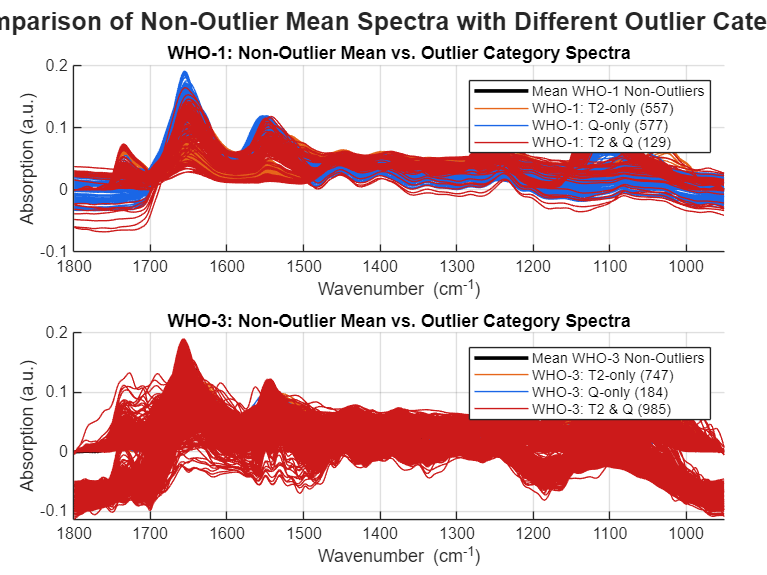


figOutlierCatSpectra = figure('Name', 'Spectra of Outlier Categories vs. Non-Outlier Mean', 'Position', [100, 50, 1200, 900]);
tl_ocs = tiledlayout(2,1, 'TileSpacing', 'compact', 'Padding', 'compact');

% Define colors for this specific plot (you can adjust these)
color_Mean_NonOutlier_Plot = [0 0 0];       % Black for mean of non-outliers
color_T2_only_Plot = [0.9, 0.4, 0.1];      % Dark Orange for T2-only
color_Q_only_Plot = [0.1, 0.4, 0.9];       % Dark Blue for Q-only
color_Both_T2Q_Plot = [0.8, 0.1, 0.1];     % Dark Red for T2 & Q
alpha_val_spectra = 0.3;                   % Transparency for individual outlier spectra
linewidth_individual_spectra = 0.5;
linewidth_mean_spectrum = 2.0;

% We need the final definition of non-outliers (those NOT flagged by T2 OR Q)
% This should be consistent with 'good_indices_logical' used for cleaning.
final_non_outlier_indices = ~(outlier_T2_logical | outlier_Q_logical);

% --- Tile 1: WHO-1 Context ---
ax1_ocs = nexttile(tl_ocs);
hold(ax1_ocs, 'on');
    
    % 1. Mean of WHO-1 Non-Outliers (Final Definition)
    isWHO1_selector = (y_train_numeric == 1);
    meanSpec_WHO1_non_out_final = mean(X_train(isWHO1_selector & final_non_outlier_indices, :), 1);
    legend_handles_ocs1 = [];
    if ~isempty(meanSpec_WHO1_non_out_final) && any(~isnan(meanSpec_WHO1_non_out_final))
        h_mean1 = plot(ax1_ocs, wavenumbers_roi, meanSpec_WHO1_non_out_final, ...
             'Color', color_Mean_NonOutlier_Plot, ...
             'LineWidth', linewidth_mean_spectrum, ...
             'DisplayName', 'Mean WHO-1 Non-Outliers');
        legend_handles_ocs1 = [legend_handles_ocs1, h_mean1];
    end

    % 2. T2-only Outliers for WHO-1
    idx_T2_only_WHO1 = isWHO1_selector & outlier_T2_logical & ~outlier_Q_logical;
    spectra_T2_only_WHO1 = X_train(idx_T2_only_WHO1, :);
    if ~isempty(spectra_T2_only_WHO1)
        for k=1:size(spectra_T2_only_WHO1,1)
            plot(ax1_ocs, wavenumbers_roi, spectra_T2_only_WHO1(k,:), 'Color', [color_T2_only_Plot, alpha_val_spectra], 'LineWidth', linewidth_individual_spectra, 'HandleVisibility', 'off');
        end
        h_t2_1 = plot(ax1_ocs, wavenumbers_roi, spectra_T2_only_WHO1(1,:), 'Color', [color_T2_only_Plot, alpha_val_spectra], 'LineWidth', linewidth_individual_spectra, 'DisplayName', ['WHO-1: T2-only (' num2str(sum(idx_T2_only_WHO1)) ')']);
        legend_handles_ocs1 = [legend_handles_ocs1, h_t2_1];
    end

    % 3. Q-only Outliers for WHO-1
    idx_Q_only_WHO1 = isWHO1_selector & ~outlier_T2_logical & outlier_Q_logical;
    spectra_Q_only_WHO1 = X_train(idx_Q_only_WHO1, :);
    if ~isempty(spectra_Q_only_WHO1)
        for k=1:size(spectra_Q_only_WHO1,1)
            plot(ax1_ocs, wavenumbers_roi, spectra_Q_only_WHO1(k,:), 'Color', [color_Q_only_Plot, alpha_val_spectra], 'LineWidth', linewidth_individual_spectra, 'HandleVisibility', 'off');
        end
        h_q_1 = plot(ax1_ocs, wavenumbers_roi, spectra_Q_only_WHO1(1,:), 'Color', [color_Q_only_Plot, alpha_val_spectra], 'LineWidth', linewidth_individual_spectra, 'DisplayName', ['WHO-1: Q-only (' num2str(sum(idx_Q_only_WHO1)) ')']);
        legend_handles_ocs1 = [legend_handles_ocs1, h_q_1];
    end

    % 4. Both T2 & Q Outliers for WHO-1
    idx_Both_T2Q_WHO1 = isWHO1_selector & outlier_T2_logical & outlier_Q_logical;
    spectra_Both_T2Q_WHO1 = X_train(idx_Both_T2Q_WHO1, :);
    if ~isempty(spectra_Both_T2Q_WHO1)
        for k=1:size(spectra_Both_T2Q_WHO1,1)
            plot(ax1_ocs, wavenumbers_roi, spectra_Both_T2Q_WHO1(k,:), 'Color', [color_Both_T2Q_Plot, alpha_val_spectra], 'LineWidth', linewidth_individual_spectra, 'HandleVisibility', 'off');
        end
        h_both_1 = plot(ax1_ocs, wavenumbers_roi, spectra_Both_T2Q_WHO1(1,:), 'Color', [color_Both_T2Q_Plot, alpha_val_spectra], 'LineWidth', linewidth_individual_spectra, 'DisplayName', ['WHO-1: T2 & Q (' num2str(sum(idx_Both_T2Q_WHO1)) ')']);
        legend_handles_ocs1 = [legend_handles_ocs1, h_both_1];
    end
hold(ax1_ocs, 'off');
title(ax1_ocs, 'WHO-1: Non-Outlier Mean vs. Outlier Category Spectra');
xlabel(ax1_ocs, 'Wavenumber (cm^{-1})'); ylabel(ax1_ocs, 'Absorption (a.u.)');
xlim(ax1_ocs, [950 1800]); ylim(ax1_ocs, 'auto'); 
if ~isempty(legend_handles_ocs1); legend(ax1_ocs, legend_handles_ocs1, 'Location', 'northeast', 'FontSize', 8); end
ax1_ocs.XDir = 'reverse'; grid(ax1_ocs, 'on');

% --- Tile 2: WHO-3 Context ---
ax2_ocs = nexttile(tl_ocs);
hold(ax2_ocs, 'on');

    % 1. Mean of WHO-3 Non-Outliers (Final Definition)
    isWHO3_selector = (y_train_numeric == 3);
    meanSpec_WHO3_non_out_final = mean(X_train(isWHO3_selector & final_non_outlier_indices, :), 1);
    legend_handles_ocs2 = [];
    if ~isempty(meanSpec_WHO3_non_out_final) && any(~isnan(meanSpec_WHO3_non_out_final))
       h_mean3 = plot(ax2_ocs, wavenumbers_roi, meanSpec_WHO3_non_out_final, ...
            'Color', color_Mean_NonOutlier_Plot, ...
            'LineWidth', linewidth_mean_spectrum, ...
            'DisplayName', 'Mean WHO-3 Non-Outliers');
        legend_handles_ocs2 = [legend_handles_ocs2, h_mean3];
    end

    % 2. T2-only Outliers for WHO-3
    idx_T2_only_WHO3 = isWHO3_selector & outlier_T2_logical & ~outlier_Q_logical;
    spectra_T2_only_WHO3 = X_train(idx_T2_only_WHO3, :);
    if ~isempty(spectra_T2_only_WHO3)
        for k=1:size(spectra_T2_only_WHO3,1)
            plot(ax2_ocs, wavenumbers_roi, spectra_T2_only_WHO3(k,:), 'Color', [color_T2_only_Plot, alpha_val_spectra], 'LineWidth', linewidth_individual_spectra, 'HandleVisibility', 'off');
        end
        h_t2_3 = plot(ax2_ocs, wavenumbers_roi, spectra_T2_only_WHO3(1,:), 'Color', [color_T2_only_Plot, alpha_val_spectra], 'LineWidth', linewidth_individual_spectra, 'DisplayName', ['WHO-3: T2-only (' num2str(sum(idx_T2_only_WHO3)) ')']);
        legend_handles_ocs2 = [legend_handles_ocs2, h_t2_3];
    end

    % 3. Q-only Outliers for WHO-3
    idx_Q_only_WHO3 = isWHO3_selector & ~outlier_T2_logical & outlier_Q_logical;
    spectra_Q_only_WHO3 = X_train(idx_Q_only_WHO3, :);
    if ~isempty(spectra_Q_only_WHO3)
        for k=1:size(spectra_Q_only_WHO3,1)
            plot(ax2_ocs, wavenumbers_roi, spectra_Q_only_WHO3(k,:), 'Color', [color_Q_only_Plot, alpha_val_spectra], 'LineWidth', linewidth_individual_spectra, 'HandleVisibility', 'off');
        end
        h_q_3 = plot(ax2_ocs, wavenumbers_roi, spectra_Q_only_WHO3(1,:), 'Color', [color_Q_only_Plot, alpha_val_spectra], 'LineWidth', linewidth_individual_spectra, 'DisplayName', ['WHO-3: Q-only (' num2str(sum(idx_Q_only_WHO3)) ')']);
        legend_handles_ocs2 = [legend_handles_ocs2, h_q_3];
    end

    % 4. Both T2 & Q Outliers for WHO-3
    idx_Both_T2Q_WHO3 = isWHO3_selector & outlier_T2_logical & outlier_Q_logical;
    spectra_Both_T2Q_WHO3 = X_train(idx_Both_T2Q_WHO3, :);
    if ~isempty(spectra_Both_T2Q_WHO3)
        for k=1:size(spectra_Both_T2Q_WHO3,1)
            plot(ax2_ocs, wavenumbers_roi, spectra_Both_T2Q_WHO3(k,:), 'Color', [color_Both_T2Q_Plot, alpha_val_spectra], 'LineWidth', linewidth_individual_spectra, 'HandleVisibility', 'off');
        end
        h_both_3 = plot(ax2_ocs, wavenumbers_roi, spectra_Both_T2Q_WHO3(1,:), 'Color', [color_Both_T2Q_Plot, alpha_val_spectra], 'LineWidth', linewidth_individual_spectra, 'DisplayName', ['WHO-3: T2 & Q (' num2str(sum(idx_Both_T2Q_WHO3)) ')']);
        legend_handles_ocs2 = [legend_handles_ocs2, h_both_3];
    end
hold(ax2_ocs, 'off');
title(ax2_ocs, 'WHO-3: Non-Outlier Mean vs. Outlier Category Spectra');
xlabel(ax2_ocs, 'Wavenumber (cm^{-1})'); ylabel(ax2_ocs, 'Absorption (a.u.)');
xlim(ax2_ocs, [950 1800]); ylim(ax2_ocs, 'auto');
if ~isempty(legend_handles_ocs2); legend(ax2_ocs, legend_handles_ocs2, 'Location', 'northeast', 'FontSize', 8); end
ax2_ocs.XDir = 'reverse'; grid(ax2_ocs, 'on');

% Add a main title to the tiled layout
title(tl_ocs, 'Comparison of Non-Outlier Mean Spectra with Different Outlier Categories', 'FontSize', 14, 'FontWeight', 'bold');

% --- Save the figure ---
% datePrefix should be defined (e.g., '20250514')
figName_OutlierCatSpectra_tiff = strcat(datePrefix, '_Spectra_OutlierCategories_vs_Mean.tiff');
exportgraphics(figOutlierCatSpectra, fullfile(figuresDir, figName_OutlierCatSpectra_tiff), 'Resolution', 300);

figName_OutlierCatSpectra_fig = strcat(datePrefix, '_Spectra_OutlierCategories_vs_Mean.fig');
savefig(figOutlierCatSpectra, fullfile(figuresDir, figName_OutlierCatSpectra_fig));
disp(['Plot visualizing spectra of outlier categories saved as: ' fullfile(figuresDir, figName_OutlierCatSpectra_tiff)]);

Plot visualizing spectra of outlier categories saved as: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\figures\20250514_Spectra_OutlierCategories_vs_Mean.tiff



% ... (End of Section 9 or continued visualizations) ...

% Insert this as a new plot, e.g., Plot 8, within %% --- 9. Visualize Results ---

% Plot 8: Spectra by Outlier Type, Separated by WHO Grade (3x2 Layout - Neat Y-Axis Ticks)
disp('Creating 3x2 plot: Spectra by outlier type, WHO split, common Y-axis with neat ticks...');

Creating 3x2 plot: Spectra by outlier type, WHO split, common Y-axis with neat ticks...



% --- 1. Determine Global Y-Limits and "Nice" Ticks for all subplots ---
all_spectra_for_this_figure = [];
idx_T2_only_global = outlier_T2_logical & ~outlier_Q_logical;
if any(idx_T2_only_global); all_spectra_for_this_figure = [all_spectra_for_this_figure; X_train(idx_T2_only_global, :)]; end
idx_Q_only_global = ~outlier_T2_logical & outlier_Q_logical;
if any(idx_Q_only_global); all_spectra_for_this_figure = [all_spectra_for_this_figure; X_train(idx_Q_only_global, :)]; end
idx_Both_T2Q_global = outlier_T2_logical & outlier_Q_logical;
if any(idx_Both_T2Q_global); all_spectra_for_this_figure = [all_spectra_for_this_figure; X_train(idx_Both_T2Q_global, :)]; end

common_ylim_plot8_final = [0 1]; % Default fallback
final_yticks_plot8 = linspace(0,1,5); % Default fallback

if ~isempty(all_spectra_for_this_figure)
    min_y_data = min(all_spectra_for_this_figure(:));
    max_y_data = max(all_spectra_for_this_figure(:));

    if min_y_data == max_y_data % Handle case where all data points are identical
        padded_min_y = min_y_data - 0.1; % Create some range
        padded_max_y = max_y_data + 0.1;
        if padded_min_y == padded_max_y; padded_max_y = padded_min_y + 0.1; end
    else
        data_range = max_y_data - min_y_data;
        padding = data_range * 0.05; % 5% padding
        padded_min_y = min_y_data - padding;
        padded_max_y = max_y_data + padding;
    end

    % Use a temporary invisible axis to get MATLAB's "nice" tick suggestions
    temp_fig_for_ticks = figure('Visible', 'off'); % Ensure it's off-screen
    temp_ax_for_ticks = axes(temp_fig_for_ticks);
    ylim(temp_ax_for_ticks, [padded_min_y, padded_max_y]);
    final_yticks_plot8 = get(temp_ax_for_ticks, 'YTick');
    close(temp_fig_for_ticks); % Close the temporary figure

    % Ensure there are at least two ticks for a valid range
    if length(final_yticks_plot8) < 2
        final_yticks_plot8 = linspace(padded_min_y, padded_max_y, 5); % Fallback to 5 ticks
        if abs(padded_min_y - padded_max_y) < 1e-9 % Handle very small or zero range after padding
            final_yticks_plot8 = linspace(padded_min_y - 0.1, padded_max_y + 0.1, 5);
             % Further fallback if still all same (e.g. input was single point 0)
            if all(abs(diff(final_yticks_plot8)) < 1e-9) 
                final_yticks_plot8 = final_yticks_plot8(1) + [-0.2 -0.1 0 0.1 0.2];
            end
        end
    end
    
    common_ylim_plot8_final = [min(final_yticks_plot8), max(final_yticks_plot8)]; % Ylim now exactly spans the nice ticks
    
    if any(isnan(common_ylim_plot8_final)) || common_ylim_plot8_final(1) >= common_ylim_plot8_final(2)
        disp('Warning: Y-limit calculation for Plot 8 resulted in NaN or invalid range. Using default [0 1].');
        common_ylim_plot8_final = [0 1];
        final_yticks_plot8 = linspace(0,1,5);
    end
else
    disp('No outlier spectra found to determine common Y-axis for Plot 8. Using default [0 1] and 5 ticks.');
end
disp(['Common Y-axis for Plot 8 will be: [' num2str(common_ylim_plot8_final(1)) ', ' num2str(common_ylim_plot8_final(2)) ']']);

Common Y-axis for Plot 8 will be: [-0.1, 0.2]


disp(['Y-ticks for Plot 8 will be: [' num2str(final_yticks_plot8) ']']);

Y-ticks for Plot 8 will be: [-0.1       -0.05  1.3878e-17        0.05         0.1        0.15         0.2]


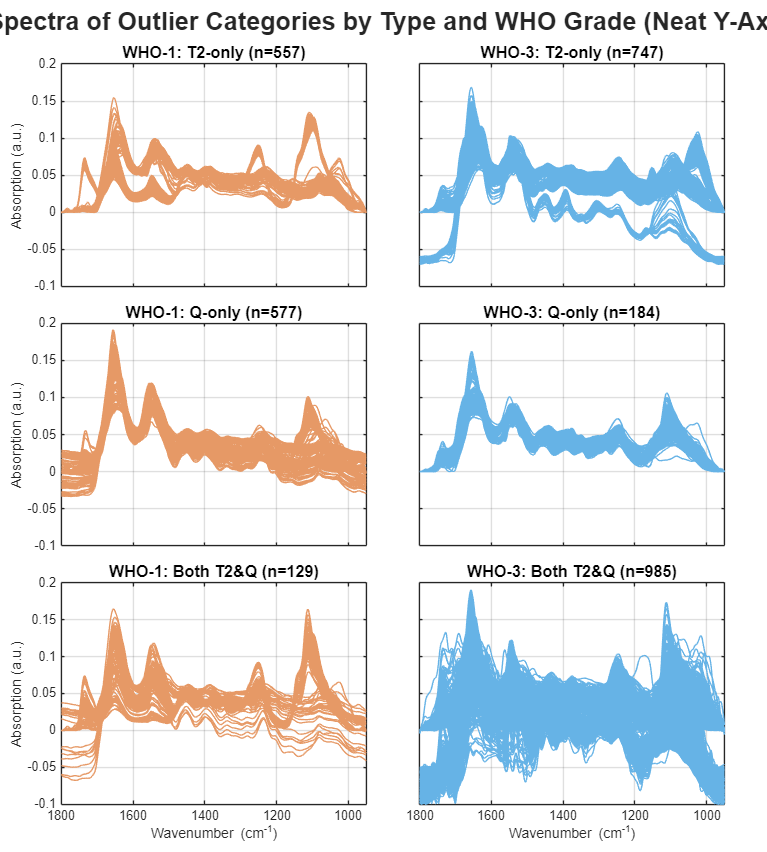



figSpectraTypeWHORefined = figure('Name', 'Outlier Spectra by Type and WHO Grade (Neat Y-Axis)', 'Position', [50, 50, 900, 1000]);
tl_stw_refined = tiledlayout(3,2, 'TileSpacing', 'compact', 'Padding', 'compact'); 

% Styling (remains the same)
alpha_individual_outlier_spectra = 0.35;
linewidth_individual_outlier_spectra_stw = 0.5;
subplot_title_fontsize_stw = 9;
subplot_axlabel_fontsize_stw = 8;
subplot_ticklabel_fontsize_stw = 7; 

outlier_types_to_plot = {'T2only', 'Qonly', 'BothT2Q'};
who_grades_to_plot_numeric = [1, 3]; 

for row_idx = 1:length(outlier_types_to_plot)
    current_outlier_type = outlier_types_to_plot{row_idx};
    
    for col_idx = 1:length(who_grades_to_plot_numeric)
        ax = nexttile(tl_stw_refined);
        hold(ax, 'on');
        box(ax, 'on'); 

        current_who_grade_numeric = who_grades_to_plot_numeric(col_idx);
        
        % ... (spectra selection logic remains the same as previous version) ...
        spectra_to_plot = [];
        idx_selector = [];
        plot_color_individual = [];
        
        if current_who_grade_numeric == 1
            is_current_grade = (y_train_numeric == 1);
            plot_color_individual = colorWHO1;
            grade_string = 'WHO-1';
        else 
            is_current_grade = (y_train_numeric == 3);
            plot_color_individual = colorWHO3;
            grade_string = 'WHO-3';
        end

        title_string_type_part = '';
        switch current_outlier_type
            case 'T2only'
                idx_selector = is_current_grade & outlier_T2_logical & ~outlier_Q_logical;
                title_string_type_part = 'T2-only';
            case 'Qonly'
                idx_selector = is_current_grade & ~outlier_T2_logical & outlier_Q_logical;
                title_string_type_part = 'Q-only';
            case 'BothT2Q'
                idx_selector = is_current_grade & outlier_T2_logical & outlier_Q_logical;
                title_string_type_part = 'Both T2&Q';
        end
        
        spectra_to_plot = X_train(idx_selector, :);
        num_spectra_in_plot = sum(idx_selector);

        if ~isempty(spectra_to_plot)
            for k=1:size(spectra_to_plot,1)
                plot(ax, wavenumbers_roi, spectra_to_plot(k,:), ...
                     'Color', [plot_color_individual, alpha_individual_outlier_spectra], ...
                     'LineWidth', linewidth_individual_outlier_spectra_stw);
            end
        end
        
        hold(ax, 'off');
        title(ax, [grade_string, ': ', title_string_type_part, ' (n=', num2str(num_spectra_in_plot), ')'], ...
              'FontSize', subplot_title_fontsize_stw);
        
        xlim(ax, [950 1800]);
        ylim(ax, common_ylim_plot8_final); % APPLY COMMON Y-LIMITS (now exact bounds of ticks)
        ax.XDir = 'reverse';
        grid(ax, 'on'); 

        % --- Tick and Label Control with new common_ylim_plot8_final and final_yticks_plot8 ---
        ax.XAxis.FontSize = subplot_ticklabel_fontsize_stw;
        ax.YAxis.FontSize = subplot_ticklabel_fontsize_stw;

        % Y-axis ticks and labels (only for the first column)
        if col_idx == 1 
            set(ax, 'YTick', final_yticks_plot8); % Set the determined "nice" ticks
            set(ax, 'YTickLabelMode', 'auto'); % Let MATLAB format them
            ylabel(ax, 'Absorption (a.u.)', 'FontSize', subplot_axlabel_fontsize_stw);
        else 
            set(ax, 'YTick', final_yticks_plot8); % Use same tick positions for grid consistency
            set(ax, 'YTickLabel', []);          % But hide labels
        end

        % X-axis ticks and labels (only for the bottom row)
        if row_idx == 3 
            set(ax, 'XTickMode', 'auto'); % Let MATLAB choose X ticks based on xlim
            set(ax, 'XTickLabelMode', 'auto'); 
            xlabel(ax, 'Wavenumber (cm^{-1})', 'FontSize', subplot_axlabel_fontsize_stw);
        else 
            set(ax, 'XTickMode', 'auto'); % Allow X ticks for grid
            set(ax, 'XTickLabel', []);    % But hide labels
        end
    end
end

overall_plot_title = 'Spectra of Outlier Categories by Type and WHO Grade (Neat Y-Axis)'; 
title(tl_stw_refined, overall_plot_title, 'FontSize', 14, 'FontWeight', 'bold');

% --- Save the figure ---
% datePrefix from script setup, e.g., '20250514'
figName_SpectraTypeWHONeatY_tiff = strcat(datePrefix, '_Spectra_OutlierType_WHOSplit_NeatY.tiff');
exportgraphics(figSpectraTypeWHORefined, fullfile(figuresDir, figName_SpectraTypeWHONeatY_tiff), 'Resolution', 300);

figName_SpectraTypeWHONeatY_fig = strcat(datePrefix, '_Spectra_OutlierType_WHOSplit_NeatY.fig');
savefig(figSpectraTypeWHORefined, fullfile(figuresDir, figName_SpectraTypeWHONeatY_fig));
disp(['Plot visualizing spectra by outlier type (Neat Y-Axis) saved as: ' fullfile(figuresDir, figName_SpectraTypeWHONeatY_tiff)]);

Plot visualizing spectra by outlier type (Neat Y-Axis) saved as: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\figures\20250514_Spectra_OutlierType_WHOSplit_NeatY.tiff



% ... (End of Section 9 or continued visualizations) ...

disp('Starting combined patient-wise outlier display (7x4 Layout, revised ticks/legends)...');

Starting combined patient-wise outlier display (7x4 Layout, revised ticks/legends)...



% --- Assume previous setup and data loading ---
% Variables expected: X_train, y_train_categorical, Patient_ID_train, 
% outlier_indices_logical, wavenumbers_roi, colorWHO1, colorWHO3, colorOutlier,
% datePrefix, figuresDir

% --- 1. Identify patients with outliers and their info ---
unique_patient_ids_in_train = unique(Patient_ID_train);
patients_with_outliers_info = {}; 

for i = 1:length(unique_patient_ids_in_train)
    current_patient_id_temp = unique_patient_ids_in_train{i};
    patient_global_indices_temp = find(strcmp(Patient_ID_train, current_patient_id_temp));
    if isempty(patient_global_indices_temp)
        continue;
    end
    patient_outlier_status_temp = outlier_indices_logical(patient_global_indices_temp);
    num_patient_outliers = sum(patient_outlier_status_temp);
    
    if num_patient_outliers > 0
        patient_who_grade_temp = y_train_categorical(patient_global_indices_temp(1));
        patients_with_outliers_info{end+1,1} = {current_patient_id_temp, num_patient_outliers, patient_who_grade_temp};
    end
end

patient_plot_count = size(patients_with_outliers_info, 1);

if patient_plot_count == 0
    disp('No patients with outliers found in the training set for combined display.');
    return; 
end

fprintf('%d patients with outliers will be displayed in the tiled layout.\n', patient_plot_count);

28 patients with outliers will be displayed in the tiled layout.



% --- 2. Define tiledlayout dimensions (7 rows, 4 columns) ---
nrows_layout = 7;
ncols_layout = 4;
total_tiles = nrows_layout * ncols_layout;

if patient_plot_count > total_tiles
    warning('Number of patients with outliers (%d) exceeds available tiles in 7x4 layout (%d). Only the first %d will be shown.', ...
            patient_plot_count, total_tiles, total_tiles);
elseif patient_plot_count < total_tiles && patient_plot_count ~= 28 % If user said 28, but it's not.
     warning('Number of patients with outliers (%d) is less than available tiles in 7x4 layout (%d). Some tiles will be empty. User expected 28 plots for a full 4x7 or 7x4 grid.', ...
            patient_plot_count, total_tiles);
end
disp(['Using a fixed layout: ' num2str(nrows_layout) ' rows x ' num2str(ncols_layout) ' columns.']);

Using a fixed layout: 7 rows x 4 columns.



% --- 3. Create main figure and TiledLayout ---
fig_width = min(1300, ncols_layout * 280 + 100); % Adjusted for 4 columns
fig_height = min(1100, nrows_layout * 150 + 150); % Adjusted for 7 rows, more height needed

figCombined = figure('Name', 'Patient Outlier Overview (7x4)', ...
                     'Position', [50, 30, fig_width, fig_height], ...
                     'PaperUnits', 'normalized', ...
                     'PaperPositionMode', 'auto');

tl = tiledlayout(nrows_layout, ncols_layout, 'TileSpacing', 'compact', 'Padding', 'compact');

% --- 4. Overall figure title ---
overall_main_title = "Outlier-Spektren im Training-Set nach Hotelling's T2 vs. Q-Test"; % As requested
title(tl, overall_main_title, 'FontSize', 16, 'FontWeight', 'bold');

% Styling for subplots
linewidth_non_outlier_patient = 0.6;
linewidth_outlier_patient = 0.8;
alpha_patient_non_outlier = 0.35;
subplot_title_fontsize = 8; % Increased title font size
subplot_axlabel_fontsize = 7;
subplot_ticklabel_fontsize = 6;
legend_fontsize_main = 7; 

% Initialize handles for legend items
h_legend_WHO1_norm = [];
h_legend_WHO3_norm = [];
h_legend_outlier_common = [];

% --- 5. Loop through patients with outliers and plot ---
for i = 1:min(patient_plot_count, total_tiles) 
    current_patient_data = patients_with_outliers_info{i};
    current_patient_id = current_patient_data{1};
    num_outliers_for_patient = current_patient_data{2};
    patient_who_grade = current_patient_data{3};
    
    ax = nexttile; 
    hold(ax, 'on');
    box(ax, 'on'); % Complete box around each plot

    patient_global_indices = find(strcmp(Patient_ID_train, current_patient_id));
    patient_spectra_all = X_train(patient_global_indices, :);
    patient_outlier_status = outlier_indices_logical(patient_global_indices);
    
    patient_spectra_outliers = patient_spectra_all(patient_outlier_status, :);
    patient_spectra_non_outliers = patient_spectra_all(~patient_outlier_status, :);
    
    % Plot non-outlier spectra
    if ~isempty(patient_spectra_non_outliers)
        temp_h_norm = [];
        for k = 1:size(patient_spectra_non_outliers, 1)
            temp_h_norm_curr = plot(ax, wavenumbers_roi, patient_spectra_non_outliers(k,:), ...
                 'HandleVisibility', 'off', 'LineWidth', linewidth_non_outlier_patient);
            if patient_who_grade == 'WHO-1'
                set(temp_h_norm_curr, 'Color', [colorWHO1, alpha_patient_non_outlier]);
                if isempty(h_legend_WHO1_norm)
                    temp_h_norm = temp_h_norm_curr;
                end
            elseif patient_who_grade == 'WHO-3'
                set(temp_h_norm_curr, 'Color', [colorWHO3, alpha_patient_non_outlier]);
                 if isempty(h_legend_WHO3_norm)
                    temp_h_norm = temp_h_norm_curr;
                 end
            else
                set(temp_h_norm_curr, 'Color', [[0.5 0.5 0.5], alpha_patient_non_outlier]);
            end
        end
        if patient_who_grade == 'WHO-1' && isempty(h_legend_WHO1_norm) && ~isempty(temp_h_norm)
            h_legend_WHO1_norm = temp_h_norm;
            set(h_legend_WHO1_norm, 'DisplayName', 'Norm (WHO-1)', 'HandleVisibility', 'on');
        elseif patient_who_grade == 'WHO-3' && isempty(h_legend_WHO3_norm) && ~isempty(temp_h_norm)
            h_legend_WHO3_norm = temp_h_norm;
            set(h_legend_WHO3_norm, 'DisplayName', 'Norm (WHO-3)', 'HandleVisibility', 'on');
        end
    end
    
    % Plot outlier spectra
    if ~isempty(patient_spectra_outliers)
        temp_h_outlier = [];
        for k = 1:size(patient_spectra_outliers, 1)
            temp_h_outlier_curr = plot(ax, wavenumbers_roi, patient_spectra_outliers(k,:), ...
                 'Color', [colorOutlier, 0.6], ...
                 'LineWidth', linewidth_outlier_patient, 'HandleVisibility', 'off');
            if isempty(h_legend_outlier_common)
                temp_h_outlier = temp_h_outlier_curr;
            end
        end
        if isempty(h_legend_outlier_common) && ~isempty(temp_h_outlier)
            h_legend_outlier_common = temp_h_outlier;
            set(h_legend_outlier_common, 'DisplayName', 'Outlier', 'HandleVisibility', 'on');
        end
    end
    
    hold(ax, 'off');
    xlim(ax, [950 1800]); 
    ylim(ax, 'auto'); 
    
    % Ticks and Tick Labels
    set(ax, 'XTickMode', 'auto', 'YTickMode', 'auto'); % Bring back tick marks
    ax.XAxis.FontSize = subplot_ticklabel_fontsize;
    ax.YAxis.FontSize = subplot_ticklabel_fontsize;

    current_tile_index = get(ax, 'Layout').Tile; 
    % Y-axis label for the leftmost column
    if mod(current_tile_index -1, ncols_layout) == 0 
         ylabel(ax, 'Abs.', 'FontSize', subplot_axlabel_fontsize);
    else
         set(ax, 'YTickLabel', []); % No Y-tick LABELS for inner columns
    end
    % X-axis label for the bottommost row
    if current_tile_index > (nrows_layout-1)*ncols_layout && current_tile_index <= total_tiles
        xlabel(ax, 'Wavenumber', 'FontSize', subplot_axlabel_fontsize);
    else
        set(ax, 'XTickLabel', []); % No X-tick LABELS for inner rows
    end
    
    title(ax, sprintf('%s (n=%d)', current_patient_id, num_outliers_for_patient), 'FontSize', subplot_title_fontsize, 'FontWeight', 'normal');
    ax.XDir = 'reverse'; % Keep wavenumbers decreasing
    grid(ax, 'off'); % Grid off for cleaner subplots
end

% --- 6. Place Legends ---
% WHO-1 Legend in tile 4 (top-rightmost in a 4-column layout)
target_tile_who1_legend = ncols_layout; 
if target_tile_who1_legend <= total_tiles && ~isempty(h_legend_WHO1_norm) && ~isempty(h_legend_outlier_common)
    try
        ax_for_legend1 = nexttile(target_tile_who1_legend); % Get axes of this tile
        % Check if this tile was used, otherwise legend might overlay plot from another tile if flow was on (not the case here)
        % For safety, or if tile might be empty, one could create an invisible axes for legend:
        % ax_for_legend1 = axes('Parent', figCombined, 'Position', get(nexttile(target_tile_who1_legend), 'OuterPosition'), 'Visible', 'off');
        legend(ax_for_legend1, [h_legend_WHO1_norm, h_legend_outlier_common], ...
               {'Norm (WHO-1)', 'Outlier'}, ...
               'Location', 'northeast', 'FontSize', legend_fontsize_main, 'Box', 'on', 'AutoUpdate', 'off');
        disp(['WHO-1 legend placed in tile: ' num2str(target_tile_who1_legend)]);
    catch ME_legend1
        disp(['Could not place WHO-1 legend in tile ' num2str(target_tile_who1_legend) ': ' ME_legend1.message]);
    end
elseif isempty(h_legend_WHO1_norm)
    disp('No WHO-1 non-outlier plot handle captured for legend.');
end

WHO-1 legend placed in tile: 4



% WHO-3 Legend in tile 28 (bottom-rightmost in a 7x4 layout)
target_tile_who3_legend = total_tiles; % Tile 28
if target_tile_who3_legend <= total_tiles && target_tile_who3_legend > 0 && ~isempty(h_legend_WHO3_norm) && ~isempty(h_legend_outlier_common)
    try
        ax_for_legend3 = nexttile(target_tile_who3_legend);
        legend(ax_for_legend3, [h_legend_WHO3_norm, h_legend_outlier_common], ...
               {'Norm (WHO-3)', 'Outlier'}, ...
               'Location', 'northeast', 'FontSize', legend_fontsize_main, 'Box', 'on', 'AutoUpdate', 'off');
        disp(['WHO-3 legend placed in tile: ' num2str(target_tile_who3_legend)]);
    catch ME_legend3
        disp(['Could not place WHO-3 legend in tile ' num2str(target_tile_who3_legend) ': ' ME_legend3.message]);
    end
elseif isempty(h_legend_WHO3_norm)
     disp('No WHO-3 non-outlier plot handle captured for legend.');
end

WHO-3 legend placed in tile: 28


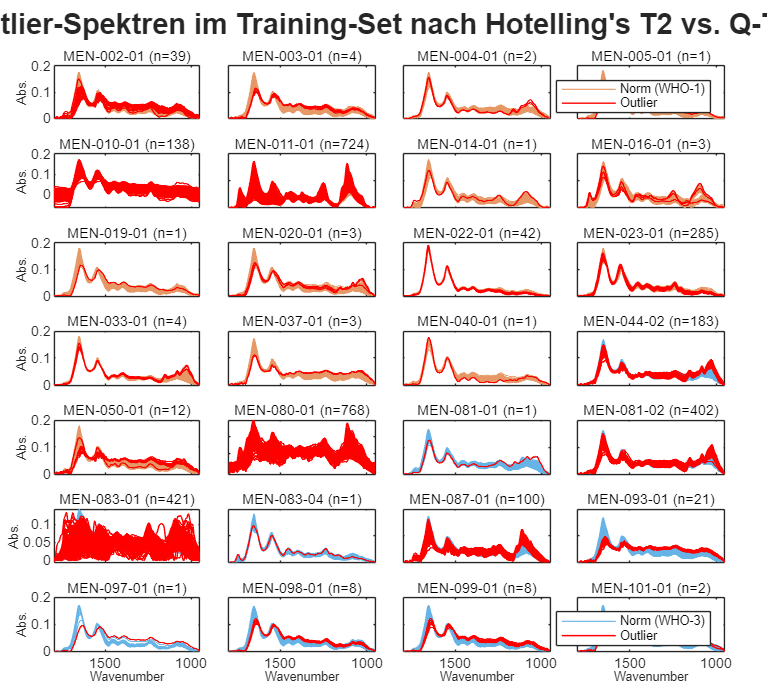

Combined patient-wise outlier figure (7x4, Revised) saved as: C:\Users\Franz\OneDrive\01_Promotion\01 Data\meningioma-ftir-classification\figures\20250514_CombinedPatientOutliers_7x4_Revised.tiff


if isempty(h_legend_outlier_common) && ( ~isempty(h_legend_WHO1_norm) || ~isempty(h_legend_WHO3_norm) )
    disp('No common outlier plot handle captured for legends.');
end


% --- 7. Save the combined figure ---
% datePrefix is '20250514'
combinedFigName_tiff = strcat(datePrefix, '_CombinedPatientOutliers_7x4_Revised.tiff');
combinedFigName_fig = strcat(datePrefix, '_CombinedPatientOutliers_7x4_Revised.fig');

try
    exportgraphics(figCombined, fullfile(figuresDir, combinedFigName_tiff), 'Resolution', 300);
    savefig(figCombined, fullfile(figuresDir, combinedFigName_fig));
    disp(['Combined patient-wise outlier figure (7x4, Revised) saved as: ' fullfile(figuresDir, combinedFigName_tiff)]);
catch ME_export_combined
    warning('Could not save combined figure: %s', ME_export_combined.message);
end